clc
clear 

[Denoising](https://www.mathworks.com/help/wavelet/denoising.html#:~:text=Denoise%20a%20Signal%20with%20the%20Wavelet%20Signal%20Denoiser&text=To%20reproduce%20the%20denoised%20signal,and%20edit%20a%20MATLAB%20script.)

[Smoothing and Denoising](https://www.mathworks.com/help/signal/smoothing-and-denoising.html)

[Denoise functions](https://www.mathworks.com/help/wavelet/referencelist.html?type=function&category=denoising)

#### Señales de muestras sin tumor

Canal 2 

Señales 21,26,31,36

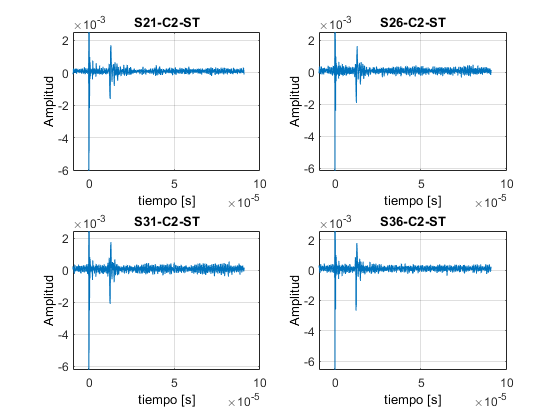


ev5=importfile("21_Ch2.csv");
b1='tiempo [s]';
b2='Amplitud';
figure(1)
a1=subplot(2,2,1);
plot(ev5.f1,ev5.f2)
title('S21-C2-ST')
grid on
xlabel(b1,'color','k')
ylabel(b2,'color','k')
%hold on

ev6=importfile("26_Ch2.csv");
a2=subplot(2,2,2);
plot(ev6.f1,ev6.f2)
title('S26-C2-ST')
grid on
xlabel(b1,'color','k')
ylabel(b2,'color','k')
%hold on

ev7=importfile("31_Ch2.csv");
a3=subplot(2,2,3);
plot(ev7.f1,ev7.f2)
title('S31-C2-ST')
grid on
xlabel(b1,'color','k')
ylabel(b2,'color','k')
%hold on

ev8=importfile("36_Ch2.csv");
a4=subplot(2,2,4);
plot(ev8.f1,ev8.f2)
title('S36-C2-ST')
xlabel(b1,'color','k')
ylabel(b2,'color','k')
grid on

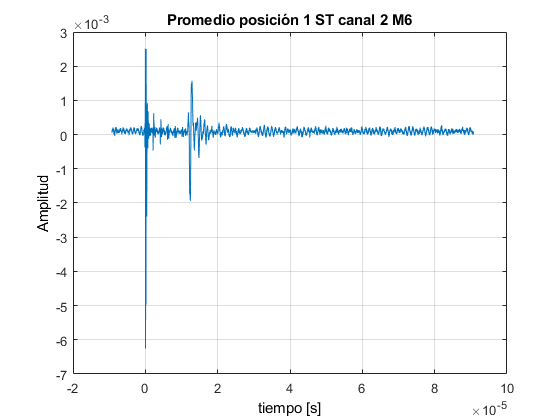

et2=(ev5.f2+ev6.f2+ev7.f2+ev8.f2)/4;
a5=subplot(1,1,1);
plot(ev5.f1,et2);
grid on
title('Promedio posición 1 ST canal 2 M6')
xlabel(b1,'color','k')
ylabel(b2,'color','k')

#### Guardar señal promedio

ev5.f2=et2;
clear ev6 ev7 ev8
%writetable(ev5,"M6LAS1P1A58.csv");


#### Leer Señal promedio

clear all 
ev5=readtable("M6LAS1P1A58.csv");
et2=ev5.f2;
iv=ev5.f1;
clear ev5


### Filtros aplicados al promedio

#### Primer filtro smotthdata

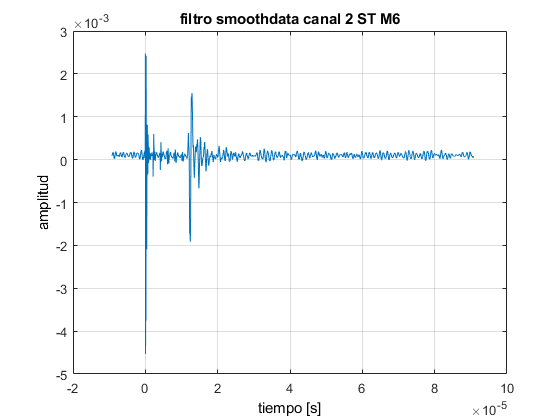

 
i11=smoothdata(et2,'gaussian');
b1='tiempo [s]';
b2='amplitud';
figure(1)
plot(iv,i11)
title('filtro smoothdata canal 2 ST M6')
xlabel(b1,'color','k')
ylabel(b2,'color','k')
grid on 

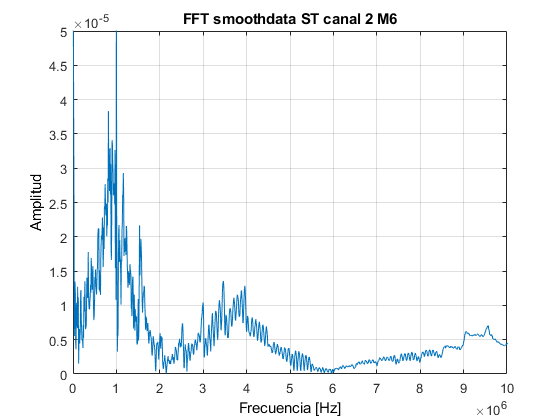


Ts=2e-9;
Fs=1/Ts;
xl1=[0 10e6];
yl1=[0 5e-5];

L=length(i11);
[fx4,fy4]=tfou(L,i11,Fs);
figure(2)
plot(fx4,fy4)
ylim(yl1)
xlim(xl1)
title('FFT smoothdata ST canal 2 M6')
ylabel('Amplitud','color','k')
xlabel('Frecuencia [Hz]','color','k')
grid on

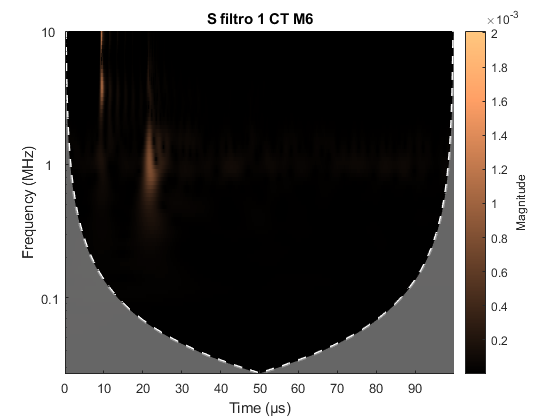


figure(3)
cwt(i11,'amor',Fs);
title('S filtro 1 CT M6');
%xlim([0.0 100])
ylim([0.0 10])
colormap copper

#### Segundo filtro wdenoise

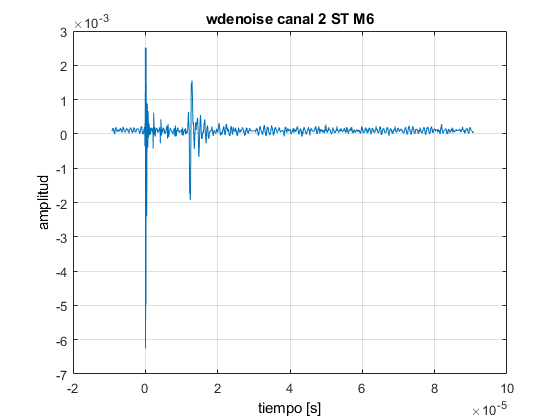


i1=wdenoise(et2,6,'DenoisingMethod','BlockJS');
figure(1)
plot(iv,i1)
title('wdenoise canal 2 ST M6')
xlabel(b1,'color','k')
ylabel(b2,'color','k')
grid on 

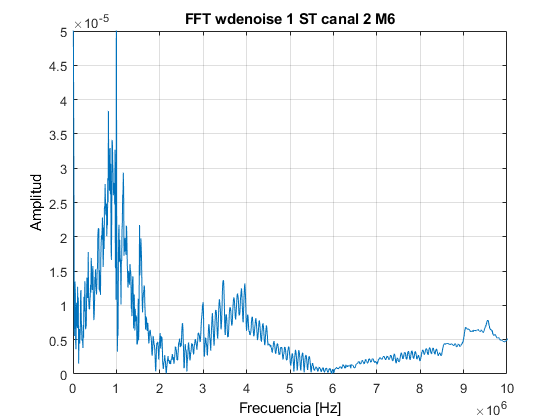

L=length(i1);
[fx4,fy4]=tfou(L,i1,Fs);
figure(2)
plot(fx4,fy4)
ylim(yl1)
xlim(xl1)
title('FFT wdenoise 1 ST canal 2 M6')
ylabel('Amplitud','color','k')
xlabel('Frecuencia [Hz]','color','k')
grid on

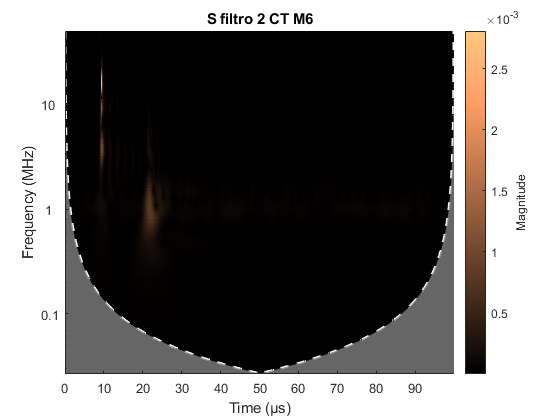


figure(3)
cwt(i1,'amor',Fs);
title('S filtro 2 CT M6');
%xlim([0.0 100])
ylim([0.0 50])
colormap copper

#### Tercer Task Smooth Data

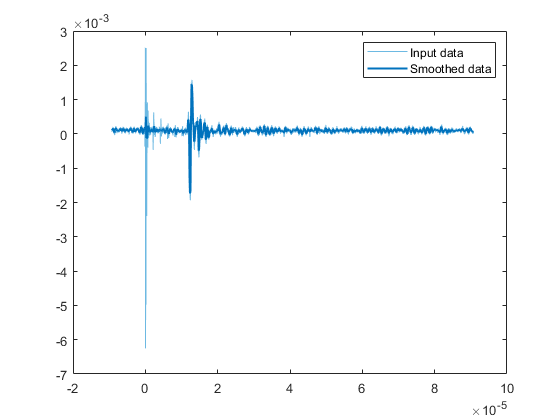

% Smooth input data
smd = smoothdata(et2,'movmedian','SmoothingFactor',0.5,...
    'SamplePoints',iv);

% Display results
clf
plot(iv,et2,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(iv,smd,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

#### Tercer filtro Task Smooth Data

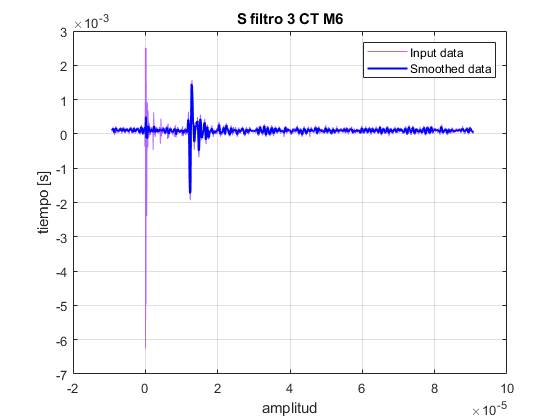


smd = smoothdata(et2,'movmedian','SmoothingFactor',0.5,...
    'SamplePoints',iv);
clf
plot(iv,et2,'Color',[178 102 255]/255,'DisplayName','Input data')
hold on
plot(iv,smd,'Color',[0 0 255]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
grid on
xlabel('amplitud')
ylabel('tiempo [s]')
title('S filtro 3 CT M6');
legend

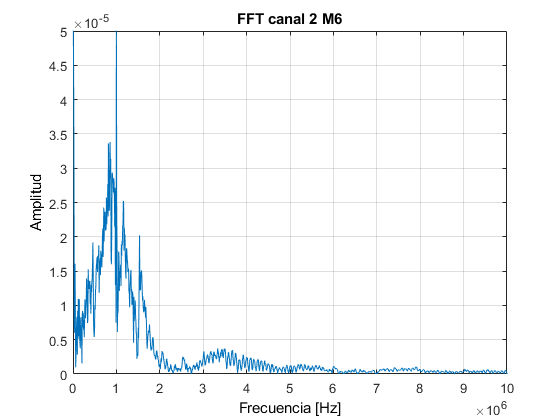



Ts=2e-9;
Fs=1/Ts;
xl1=[0 10e6];
yl1=[0 5e-5];
L=length(smd);
[fx4,fy4]=tfou(L,smd,Fs);
figure(2)
plot(fx4,fy4)
ylim(yl1)
xlim(xl1)
title('FFT canal 2 M6')
ylabel('Amplitud','color','k')
xlabel('Frecuencia [Hz]','color','k')
grid on

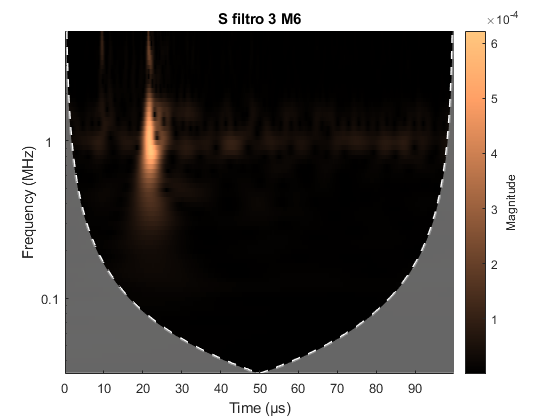


figure(3)
cwt(smd,'morse',Fs);
title('S filtro 3 M6');
%xlim([0.0 100])
ylim([0.0 5])
colormap copper

Links articulos : 

[Current and future trends](https://www.sciencedirect.com/science/article/pii/S2213597919300679) 

[Clinical imaging ](https://www.sciencedirect.com/science/article/pii/S2213597918300430)

[Human skin](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=7865979) 

[RF](http://www.inmodemd.it/files/PeerRev-Fractora_Aesthet-Dermatol-Basel_D-Duncan_M-Kreindel.pdf) 